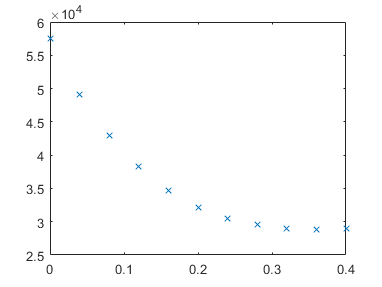

clear; close; clc;

stressesfull = [
    5.752410E+04
    4.910493E+04
    4.297333E+04
    3.831448E+04
    3.472026E+04
    3.220662E+04
    3.051528E+04
    2.952276E+04
    2.897803E+04
    2.880332E+04
    2.896937E+04
];

distancesfull = (0:.04:(.04*length(stressesfull)));
distancesfull = distancesfull(1:11);

plot(distancesfull,stressesfull,"x");

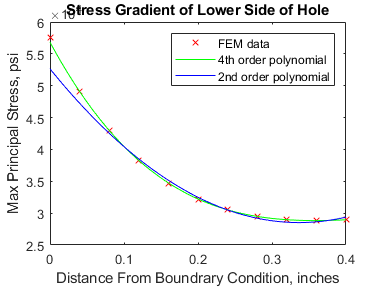


%truncate to not include the reversal
stresses = stressesfull(1:10);
distances = distancesfull(1:10);


stressfit = fit(distancesfull(2:11)',stressesfull(2:11),"poly4");
stressfit2 = fit(distancesfull(3:11)',stressesfull(3:11),"poly2");

plot(distancesfull,stressesfull,"xr"); hold on;
plot(stressfit,"g");
plot(stressfit2,"b");
title("Stress Gradient of Lower Side of Hole"); ylabel("Max Principal Stress, psi"); xlabel('Distance From Boundrary Condition, inches'); legend("FEM data","4th order polynomial","2nd order polynomial");